# CaSO4 Concentration vs Conductivity

9/27/2022  Jiayuan Liu

**CaCl2-H2O + Na2SO4 -> CaSO4 + 2NaCl**

% Molar mass
molarmass_CaCl2DH = 147.01; % g/mol
molarmass_Na2SO4 = 142.04; % g/mol

% total mass
CaCl2_g = 1.3525; % g
Na2SO4_g = 1.3068; % g

% total number of salt molecules in moles
% should be same amount for all three
CaCl2_mol = CaCl2_g / molarmass_CaCl2DH; % mol
Na2SO4_mol = Na2SO4_g / molarmass_Na2SO4; % mol
CaSO4_mol = CaCl2_mol; % mol

With 400ml water and 23mM of each salt concentration to start with, add 50mL water each time and measure the conductivity of solution until the total volume is 1000mL. 

% DI water volume/mass (with assumption 1g/ml density)
water_ml = linspace(400,1000,13); % ml

% CaSO4 concentration and two trails of measured conductivity(mS/cm)
CaSO4_concn = CaSO4_mol ./ (water_ml / 1000); % mol/L(M)
condu_one = [8, 7.25, 6.61, 6.08, 5.67, 5.26, 4.94, 4.66, 4.38, 4.15, 3.96, 3.75, 3.59];
condu_two = [8.05, 7.29, 6.65, 6.13, 5.65, 5.27, 4.93, 4.63, 4.38, 4.15, 3.94, 3.74, 3.59];

Plot each trail of data separatly. Both of them turned out to be seemingly linear, and they have pretty similar conductivity at the same salinity, which is reassuring: )

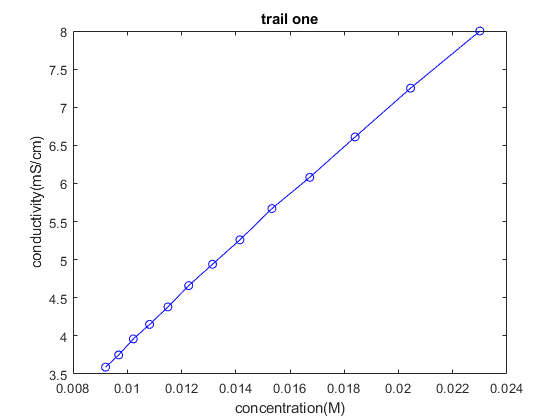

figure(1)
plot(CaSO4_concn, condu_one,"-bo");
title("trail one")
xlabel("concentration(M)")
ylabel("conductivity(mS/cm)")

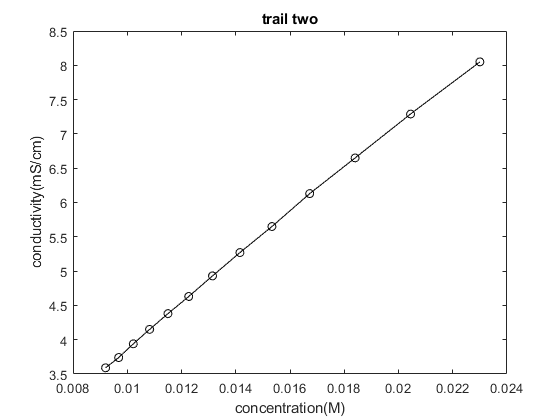


figure(2)
plot(CaSO4_concn, condu_two,"-ko");
title("trail two")
xlabel("concentration(M)")
ylabel("conductivity(mS/cm)")

Find salinity vs conductivity slope of the average of two trials using polyfit function. When it is a second degree polynomial function, it seems to fit the data points more accurately.

**conductivity (mS/cm) = - 2.056 * concn^2 + 388 * concn + 0.19 (concn in M)**

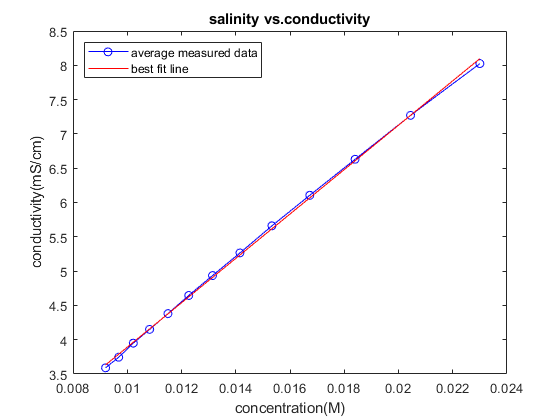

condu_avg = 0.5 * (condu_one + condu_two);
[P,R] = polyfit(CaSO4_concn, condu_avg,1);
condu_y = polyval(P,CaSO4_concn);
plot(CaSO4_concn, condu_avg,"-bo");
hold on
plot(CaSO4_concn, condu_y, "r-")
legend("average measured data", "best fit line",'location','northwest')
title("salinity vs.conductivity")
xlabel("concentration(M)")
ylabel("conductivity(mS/cm)")

 This test only covers the undersaturated solution, we need more tests for near saturation and oversaturation solution. Also, although the two tests done above have similar result, it still could be subjected to procedural errors. 